# Expand Example 3.15:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the right-sided exponential signal shown:

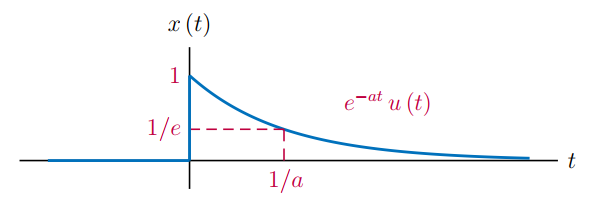


$$x(t)=e^{-at}\,u(t)\quad\quad\Longrightarrow\quad\quad
X(\omega)=\frac{1}{a+j\omega}$$


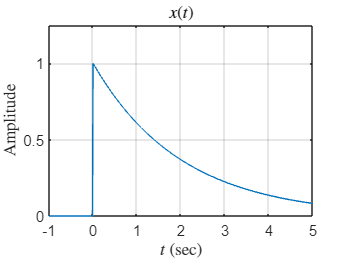

a = 0.5; % Parameter "a"
%
t = [-1:0.01:5];      % Vector of time instants
% Compute the signal
x = exp(-a*t).*(t>=0);
omg = [-10:0.02:10];  % Vector of radian frequencies
% Compute the transform
Xomg = 1./(a+j*omg);
% Graph the signal
plot(t,x); grid;
axis([-1,5,0,1.25]);
set(0,'defaultTextInterpreter','latex');
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$x(t)$');

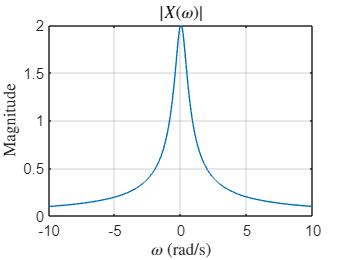

% Graph the magnitude and the phase of the transform
plot(omg,abs(Xomg)); grid;
xlabel('$\omega$ (rad/s)');
ylabel('Magnitude');
title('$|X(\omega)|$');

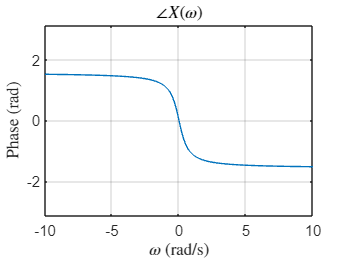

plot(omg,angle(Xomg)); grid;
axis([-10,10,-pi,pi]);
xlabel('$\omega$ (rad/s)');
ylabel('Phase (rad)');
title('$\angle X(\omega)$');

set(0,'defaultTextInterpreter','tex');